close all; clear; clc;

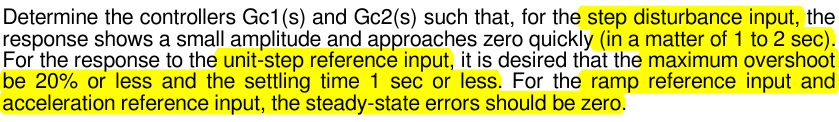

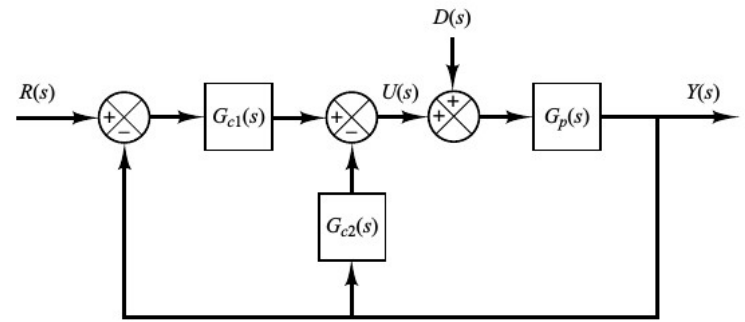

#### Función de transferencia de la planta

syms s
K  = 2;
A  = [1 1];
B  = conv([1 0],conv([1 3],[1 5]));
Gp = tf(K*A,B)

Gp =
 
       2 s + 2
  ------------------
  s^3 + 8 s^2 + 15 s
 
Continuous-time transfer function.



Gp_sym = poly2sym(K*A, s)/poly2sym(B, s)

$$Gp\_sym = \frac{2\,s+2}{s^{3}+8\,s^{2}+15\,s}$$

#### Polos/ceros de la planta

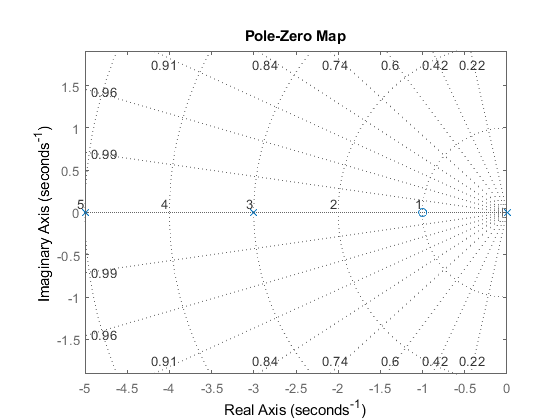

pzmap(Gp); grid on; axis('equal')

Bien, hay que notar que el sistema a lazo abierto tiene un polo en el origen, por lo tanto tiene un integrador puro a la salida.

Por ejemplo podría ser debido a que es una salida de posición obtenida por integración de la velocidad.

# Análisis de las funciones de transferencia

#### Función de transferencia del controlador auxiliar

syms kp kd ki
%Gc_sym = collect((kp + ki/s + kd*s)/poly2sym(K*A, s))
Gc_sym = collect((kp + ki/s + kd*s))

$$Gc\_sym = \frac{\mathrm{kd}\,s^{2}+\mathrm{kp}\,s+\mathrm{ki}}{s}$$

#### Función de transferencia a lazo cerrado desde la perturbación

Gd_sym = collect(Gp_sym/(1 + Gp_sym*Gc_sym))

$$Gd\_sym = \frac{2\,s^{2}+2\,s}{s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

#### Función de transferencia a lazo cerrado desde la referencia

syms Gc1_sym
Gr_sym = collect(Gc1_sym*Gp_sym/(1 + Gp_sym*Gc_sym))

$$Gr\_sym = \frac{\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym}}\right)\,s^{2}+\left(2\,{\mathrm{Gc}}_{1,\mathrm{sym}}\right)\,s}{s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

#### Polinomio del numerador

[numGr, denGr] = numden(Gr_sym);
w              = coeffs(denGr, s, 'All');
w              = sum(w(end-2:end).*s.^[2 1 0])

$$w = \left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

#### Función de transferencia de C1

numGr   = simplify(numGr/Gc1_sym);
Gc1_sym = w/numGr

$$Gc1\_sym = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}{2\,s\,\left(s+1\right)}$$

#### Función de transferencia de C2

Gc2_sym = collect(Gc_sym - Gc1_sym)

$$Gc2\_sym = \frac{\left(2\,\mathrm{kd}\right)\,s^{2}-15\,s}{2\,s+2}$$

#### Función de transferencia a LC respecto a la ref. final

Gr_sym = collect(subs(Gr_sym))

$$Gr\_sym = \frac{\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}{s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}}$$

# Asignación de polos

#### Polinomio característico a LC

denGr = collect(denGr)

$$denGr = s^{4}+\left(2\,\mathrm{kd}+8\right)\,s^{3}+\left(2\,\mathrm{kd}+2\,\mathrm{kp}+15\right)\,s^{2}+\left(2\,\mathrm{ki}+2\,\mathrm{kp}\right)\,s+2\,\mathrm{ki}$$

#### Polinomio objetivo a LC

syms w1 w2 z1 z2
obj = collect((s^2 + 2*z1*w1*s + w1^2)*(s^2 + 2*z2*w2*s + w2^2), s)

$$obj = s^{4}+\left(2\,w_{1}\,z_{1}+2\,w_{2}\,z_{2}\right)\,s^{3}+\left({w_{1}}^{2}+4\,z_{1}\,z_{2}\,w_{1}\,w_{2}+{w_{2}}^{2}\right)\,s^{2}+\left(2\,z_{2}\,{w_{1}}^{2}\,w_{2}+2\,z_{1}\,w_{1}\,{w_{2}}^{2}\right)\,s+{w_{1}}^{2}\,{w_{2}}^{2}$$

#### Asignamos valores

Vamos a dar valores **w1 y z1 dados por las características de desempeño** y luego el valor de **z2 y de las constantes del PID** van a estar determinadas **por las ecuaciones**.

Ts = 0.8 %sec

Ts = 0.8000

z1 = 0.88

z1 = 0.8800

w1 = 4/(Ts*z1)   % rad/s

w1 = 5.6818

%w1 = 10
N  = 10

N = 10

w2 = N*w1 % rad/d

w2 = 56.8182

obj         = subs(obj);
denGrCoeffs = coeffs(denGr, s, 'All');
objCoeffs   = coeffs(obj, s, 'All');
eqs         = denGrCoeffs(2:end)==objCoeffs(2:end);
sol         = solve(eqs, [kp, kd, ki, z2], 'ReturnConditions',true);

#### Soluciones obtenidas

kp_val      = double(sol.kp)

kp_val = 1.6152e+04

kd_val      = double(sol.kd)

kd_val = 1.6155e+03

ki_val      = double(sol.ki)

ki_val = 5.2110e+04

z2_val      = double(sol.z2)

z2_val = 28.4149

#### Función de transferencia del sistema a LC respecto a la ref


aux = subs(Gr_sym, [kp, kd, ki], [kp_val, kd_val, ki_val]);
[num, den] = numden(aux);
num        = sym2poly(num);
den        = sym2poly(den);
Gr         = tf(num, den)

Gr =
 
                3.909e16 s^2 + 1.501e17 s + 1.146e17
  ----------------------------------------------------------------
  1.1e12 s^4 + 3.561e15 s^3 + 3.909e16 s^2 + 1.501e17 s + 1.146e17
 
Continuous-time transfer function.



#### Función de transferencia del sistema a LC respecto de la perturbación

aux = subs(Gd_sym, [kp, kd, ki], [kp_val, kd_val, ki_val]);
[num, den] = numden(aux);
num        = sym2poly(num);
den        = sym2poly(den);
Gd         = tf(num, den)

Gd =
 
                     2.199e12 s^2 + 2.199e12 s
  ----------------------------------------------------------------
  1.1e12 s^4 + 3.561e15 s^3 + 3.909e16 s^2 + 1.501e17 s + 1.146e17
 
Continuous-time transfer function.



# Mapas de polos ceros.

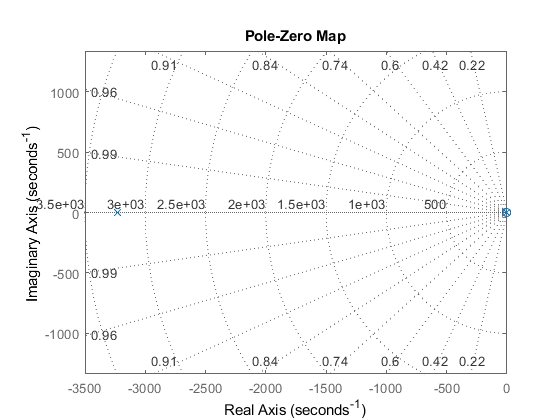

pzmap(Gr); grid on; axis('equal');

# Respuestas

#### Respuesta al escalón de perturbación

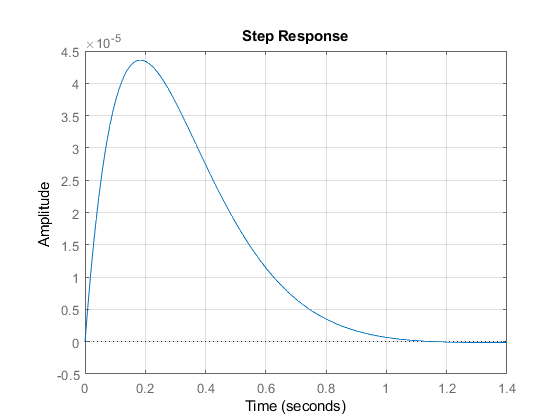

step(Gd); grid on;

stepinfo(Gd)

ans = struct with fields:
        RiseTime: 0
    SettlingTime: 0.9734
     SettlingMin: -1.3001e-07
     SettlingMax: 4.3588e-05
       Overshoot: Inf
      Undershoot: Inf
            Peak: 4.3588e-05
        PeakTime: 0.1842


#### Respuesta al escalón de referencia

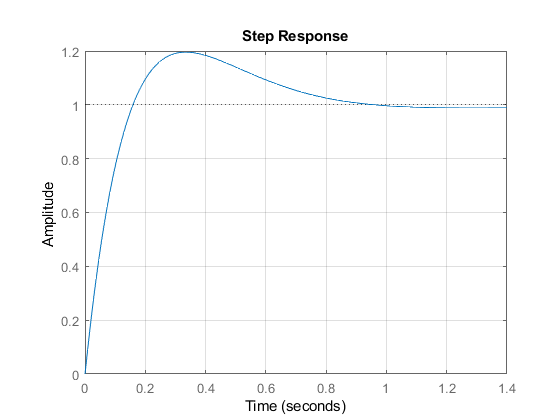

step(Gr); grid on;

stepinfo(Gr)

ans = struct with fields:
        RiseTime: 0.1195
    SettlingTime: 0.8249
     SettlingMin: 0.9332
     SettlingMax: 1.1957
       Overshoot: 19.5682
      Undershoot: 0
            Peak: 1.1957
        PeakTime: 0.3316


#### Respuesta a la rampa de referencia

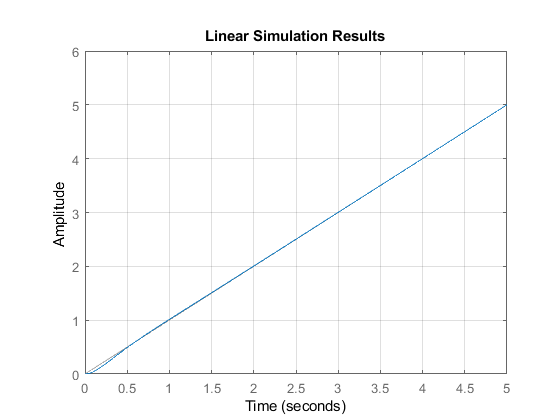

t    = 0:0.01:5;
ramp = t;
lsim(Gr, ramp, t); grid on;

#### Respuesta a la parábola de referencia

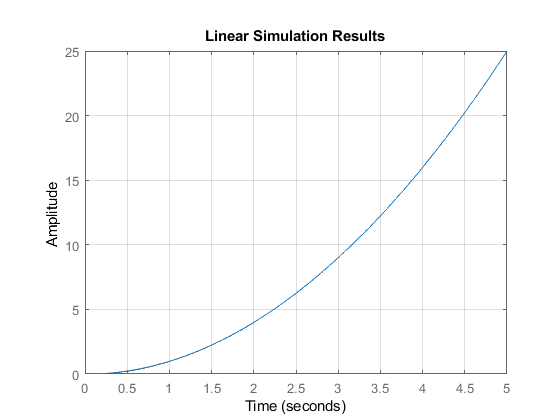

parab = t.^2;
lsim(Gr, parab, t); grid on;